clear
load walking.mat
Acceleration.time=timeElapsed(Acceleration.Timestamp);
Acc=Acceleration{:,["time", "X" ,"Y" ,"Z"]};
Acc=Acc(Acc(:,1)>10 & Acc(:,1)<20,:);

Acc =    10.0880   -0.1992  -12.5013   -0.1241
   10.1850   -0.8231  -10.6783    0.3440
   10.2820    1.9795   -5.4012    1.9205
   10.3790   -0.8782   -7.3068   -3.9724
   10.4760   -2.1712  -13.6376   -3.9918
   10.5730    0.8198   -9.3491    4.3639
   10.6700   -1.9774  -11.9848   -2.2777
   10.7670   -0.4911   -9.0347    0.8007
   10.8640   -0.9826   -8.9124    1.9418
   10.9610    1.7916   -9.4887    1.0899


Acc_ =    10.0880   12.5035
   10.1850   10.7155
   10.2820    6.0646
   10.3790    8.3630
   10.4760   14.3747
   10.5730   10.3499
   10.6700   12.3585
   10.7670    9.0834
   10.8640    9.1742
   10.9610    9.7177


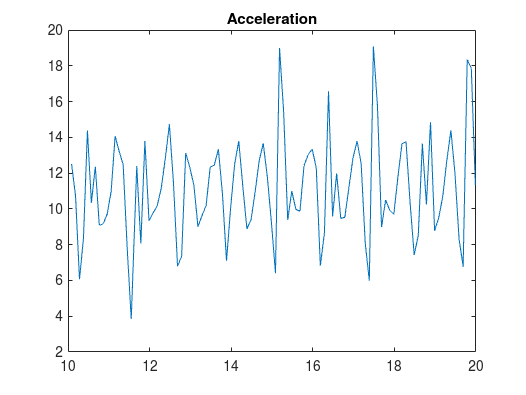

Acc_=[Acc(:,1),sqrt((Acc(:,2)).^2+(Acc(:,3)).^2+(Acc(:,4)).^2)];

[rows,~]=size(Acc_);
high_points=[0 0];
bottom_points=[0 100];
avg_value=mean(Acc_(:,2));

avg_value = 11.1672

flag=1;
top=[0 0];
bottom=[0 100];
for i=1:rows
    if flag==1
        if Acc_(i,2) >avg_value
            if Acc_(i,2)>top(2)
                top=Acc_(i,:);
            end
        else
            high_points=[high_points; top];
            flag=0;
            top=[0 0];
            if Acc_(i,2)<bottom(2)
                bottom=Acc_(i,:);
            end
        end
    else
        if Acc_(i,2)<=avg_value
            if Acc_(i,2)<bottom(2)
                bottom=Acc_(i,:);
            end
        else
            bottom_points=[bottom_points;bottom];
            flag=1;
            bottom=[0 100];
            if Acc_(i,2)>top(2)
                top=Acc_(i,:);
            end
        end
    end
end
high_points=high_points(2:end,:);

high_points =    10.0880   12.5035
   10.4760   14.3747
   10.6700   12.3585
   11.1550   14.0644
   11.6850   12.3916
   11.8850   13.7944
   12.4850   14.7298
   12.8850   13.1303
   13.6850   13.3343
   14.1850   13.7913


[rows_top,~]=size(high_points);

rows_top = 21

bottom_points=bottom_points(2:end,:);

bottom_points =    10.2820    6.0646
   10.5730   10.3499
   10.7670    9.0834
   11.5500    3.8417
   11.7850    8.0642
   11.9850    9.3426
   12.6850    6.7926
   13.1850    9.0071
   13.8850    7.0947
   14.3850    8.8869


[rows_bot,~]=size(bottom_points);

rows_bot = 21

duration=[];


duration =

     []



step_height=[];


step_height =

     []



for i=2:rows_top-1
    dur=(-high_points(i-1,1)+high_points(i+1,1))/2;
    height=(high_points(i,2)-bottom_points(i-1,2)+high_points(i,2)-bottom_points(i,2))/2;
    duration=[duration,dur];
    step_height=[step_height, height];
end
duration=duration';

duration =     0.2910
    0.3395
    0.5075
    0.3650
    0.4000
    0.5000
    0.6000
    0.6500
    0.5500
    0.5000


step_height=step_height';

step_height =     6.1675
    2.6418
    7.6019
    6.4386
    5.0909
    6.6622
    5.2305
    5.2834
    5.8005
    6.0171


result1=[duration, step_height]

result =     0.2910    6.1675
    0.3395    2.6418
    0.5075    7.6019
    0.3650    6.4386
    0.4000    5.0909
    0.5000    6.6622
    0.6000    5.2305
    0.6500    5.2834
    0.5500    5.8005
    0.5000    6.0171
